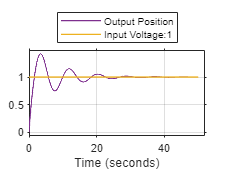

climbingPos =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


%For the climbing
%set the vars
%Cim for the CIM Motor climbing for just the situation of climbing
InputClimbing = 1;
loadInertiaClimbing = 1;
mechDampingConstantClimbing = 1; 
TerminalResistanceCim = 0.65;
TerminalInductanceCim = 0.002;
TorqueCoefCim = 141;
TorqueDisturbanceCim = 0;
load_system('ClimbSim.slx');
sim('ClimbSim.slx');
Simulink.sdi.view;
climbingPos = Simulink.sdi.snapshot("from", "opened", "to", "figure")